clf
clear
%初期化
dt = 0.05;
robot = Manipulator_3DOF_3D([0; 0; 0], [0.5; 0.5; 1; 1; 0.2], dt, true);

%順運動学
for angle = 0 : pi/10 : 2*pi
    robot = robot.setJointThetas([angle; 0; angle]);
    robot = robot.updateRobotState;
    robot.plotRobot;

    drawnow; 
end

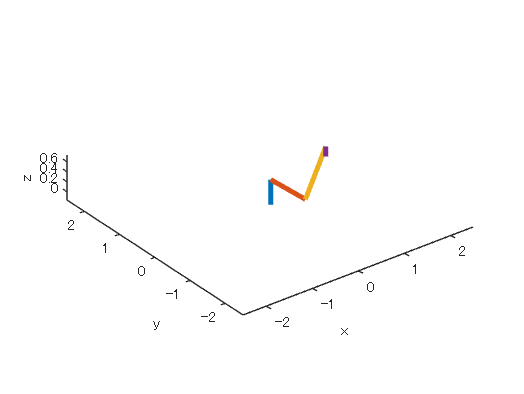

clf
clear
%初期化
dt = 0.05;
robot = Manipulator_3DOF_3D([0; 0; 0], [0; 0; 1; 1; 0.2], dt, false);

robot = robot.setPosition([1; 0; 0.5]);
robot = robot.calcInverseKinematics;
robot = robot.updateRobotState;

robot.plotRobot;


%逆運動学
% theta = 0;
% path_num_x = 2;
% for t = 0 : dt : 3
%     theta = theta + pi * dt;
%     path_num_x = path_num_x - 0.3 * dt;
%     % robot = robot.setPosition([path_num_x; 0.5*sin(theta); 0]);
%     robot = robot.setPosition([path_num_x; 0; 0]);
%     robot = robot.calcInverseKinematics;
%     robot = robot.updateRobotState;
% 
%     robot.plotRobot;
% 
%     drawnow; 
% end


% clf
% clear
% %初期化
% dt = 0.05;
% robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1; 1], dt, false);
% 
% %ヤコビアン
% for t = 0 : dt : 1
%     robot = robot.calcInverseKinematicsUsingJacobian([-1; 0], 0); %単位：[m/s, m/s], rad/s
%     robot = robot.updateRobotState;
% 
%     robot.plotRobot;
% 
%     drawnow; 
% end
% 

% clf
% clear
% 
% %軌道生成
% run("path_3DOF_2D.m");
% 
% %初期化
% robot = Manipulator_3DOF_2D([-pi/3; 2*pi/3; 0], [1.5; 1.5], dt, true);
% 
% %軌道追従（逆運動学）
% time = 0 : dt : T_f_;
% path_num = double(path);
% % path_num_y = double(path_y);
% 
% for idx = 1 : length(path_num)
%     robot = robot.setPosition([path_num(1, idx); path_num(2, idx); 0]);
%     robot = robot.setOrientation(0);
%     robot = robot.calcInverseKinematics;
%     robot = robot.updateRobotState;
% 
%     robot.plotRobot;
% 
%     drawnow; 
% end
